# Loading

simion_path = "SIM001_data/001_linear_paul_trap";
electrode_names = ["hyperbolic_trap.pa1.patxt", ...
                   "hyperbolic_trap.pa2.patxt"
                  ];
start_line = 22;
loadanyways = false;
if ~exist('dimensions', 'var') || loadanyways
    addpath(simion_path)
    [potential_maps, is_electrode, dimensions] = ...
        readFile(electrode_names, start_line);
    potential_maps = potential_maps / 10000.0;
    is_electrode = logical(is_electrode);
end

# Simulation

a               = 0.0;
q               = 0.75;
m               = 2.0;
RF_frequency    = 100.0e+6;
T               = 300.0;

end_time        = 1.0;
maxdist         = 2.5e-5;

vyy1            = 10.0;

xx1             = 3.5;
yy1             = 3.5;
zz1             = 3.5;

result = try_mathieu_aq(a, q, m, RF_frequency, T, end_time, maxdist, ...
    true, xx1, yy1, zz1, 0.0, vyy1, 0.0);

RF frequency = 100.0 MHz
RF amplitude = -6137.5 V
Endcap volts = 0.0 V
a            = 0
q            = 0.75
Simulation took 0.0169s (5136959 it/s)


fprintf("Ion lifetime in trap  was %d%% of the total simulation time.\n", ...
    round(100.0 * result.lifetime / end_time))

Ion lifetime in trap  was 2% of the total simulation time.


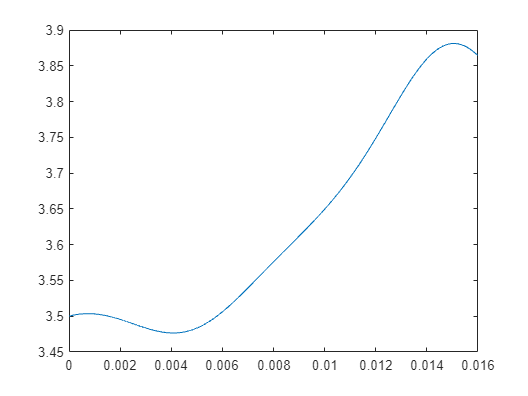

if its == 2^20
    fprintf("Simulation was terminated early due to max timestep limit (2^20) being reached.\n")
end
plot(result.ts, result.y_traj);

# Load Mathematia result for comparison